# An Introduction to Scripting with brainSurfer

The code below will help you get started scripting with the underlying brainSurfer functions. For full functionality, please see documentation within each function. Note, many of the buttons in the brainSurfer GUI do not have external functions that you can call--for example, masking, or complex operations like PCA. This tutorial assumes you are comfortable with MATLAB and brainSurfer and can implement these yourself. If you are not familiar, please see the main brainSurfer readme, which will help you understand how things work.

Before getting started with the code below, please make sure that you have the main brainSurfer directory added to your MATLAB path.

## Rendering a surface

#### Getting file paths set up

First we will setup some default settings, starting with paths to certain directories we will be pulling example data from (which come packaged with brainSurfer)

appPath = which('brainSurfer.mlapp'); % make sure brainSurfer is in your path
addpath(genpath(fileparts(appPath))); % this is just in case you have not added brainSurfer to your path but happened to run this script from the right directory...
underlaysPath = [fileparts(appPath) filesep 'brains']; % directory with some underlays for testing 
overlaysPath = [fileparts(appPath) filesep 'brainMapsforTesting']; % directory with some overlays for testing 
atlasPath = [fileparts(appPath) filesep 'atlases']; % directory with some overlays for testing 
warning('off') % we will turn warnings off -- brainSurfer will frequently warn you if the colorbins we are plotting do not make sense

#### Setting up your filename conventions for left and right hemisphere files

Many brainSurfer functions will automatically try to understand which hemisphere a file belongs to by checking the file name against certain strings. Lets set these up below and check whether automatic hemisphere detection worked. For simplicity, we explicitly pass in the hemisphere associated with many files in function calls down the line, but you can imagine automatic this process by passing in the automatically assigned hemisphere. 

But first, let's setup the strings we will check for to assign hemispheres (you can customize this however you would like for your own data). Note, within the GUI, these names are pulled from defaultSettings.json. The idea is that brainSurfer will search for the strings associated with left and right hemisphere files and automatically associate each file with a hemisphere that is organized in a structure with field names (e.g., underlay.left and underlay.right)

ln = {'lh.'};
rn = {'rh.'};

#### Loading the underlay or surface

We load in surface faces and vertices using freesurfer functions below, then use our own functions to patch data--both underlays (i.e., basic surface) and overlays (i.e., statistical maps visualized on top of surfaces). If you are working with another template, you may need to use another approach (more on that below, but we'll start with fsaverage). Let's start with underlays:

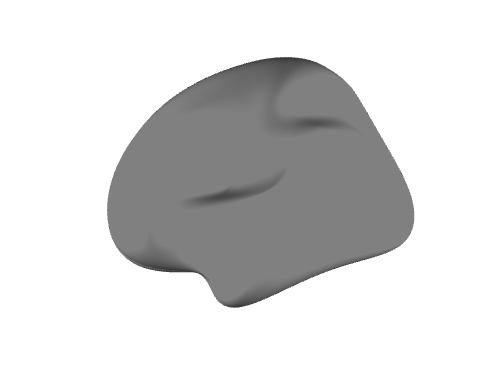

% load surface data
[vertlh,facelh] = read_surf([underlaysPath filesep 'lh.inflated']); % get vertices and faces for the lh inflated surface (fsaverage template)
[vertrh,facerh] = read_surf([underlaysPath filesep 'rh.inflated']); % get vertices and faces for the rh inflated surface (fsaverage template)

% patch surface data
[underlay, brainFig, ~, ~] = patchUnderlay(vertrh, facerh, vertlh, facelh); % note, the order you provide hemisphere data in (lh vs rh first) won't matter, the vertices are used to assign a side at this stage). You could also provide a single hemisphere and add another one later (will add example)

## Adding morphometry (e.g., sulcal/gyral) data on top of the surface

#### Loading morphometry data

The loadBrainData file loads all other brain data for brainSurfer--niftis, ciftis, annot files, etc. The one other exception is atlases, which we will get to below. First, let's load morphometry data, which will be used to color the surface we visualized above. In the example below, we test automatic hemisphere assignment to the files we load in but for the example below this will not be necessary. For more advanced programatic figure creation, you can imagine using this output to automatically pass in the correct hemisphere to downstream functions.

[hemiLH, ~, sglh, ~, ~, ~] = loadBrainData([underlaysPath filesep 'lh.curv'], underlay, ln, rn); % we pass in our strings to check against as ln and rn. I avoided commenting out the hemi output, but you can use this to make sure the right hemisphere would be assigned.

Trying to load file: lh.curv
Attempting to load as conventional nifti file...
ERROR: D:\Science\Matlab\GitHub\brainSurfer\brains\lh.curv: hdr size = 16777215, should be 348
NIFTI LOAD FAILED!
Attempting to load as gifti file...
GIFTI LOAD FAILED!
Attempting to load as cifti file...
CIFTI LOAD FAILED!
Attempting to load as annotation file...
ANNOTATION LOAD FAILED!
Attempting to load as label...
ERROR: could not open D:\Science\Matlab\GitHub\brainSurfer\brains\lh.curv.label
Attempting to load as freesurfer morphometry file...


[hemiRH, ~, sgrh, ~, ~, ~] = loadBrainData([underlaysPath filesep 'rh.curv'], underlay, ln, rn);

Trying to load file: rh.curv
Attempting to load as conventional nifti file...
ERROR: D:\Science\Matlab\GitHub\brainSurfer\brains\rh.curv: hdr size = 16777215, should be 348
NIFTI LOAD FAILED!
Attempting to load as gifti file...
GIFTI LOAD FAILED!
Attempting to load as cifti file...
CIFTI LOAD FAILED!
Attempting to load as annotation file...
ANNOTATION LOAD FAILED!
Attempting to load as label...
ERROR: could not open D:\Science\Matlab\GitHub\brainSurfer\brains\rh.curv.label
Attempting to load as freesurfer morphometry file...


#### Using patchUnderlaySG

The patchUnderlaySG function is used to assign colors to the underlay surface that you previously patched. Here is a basic example:

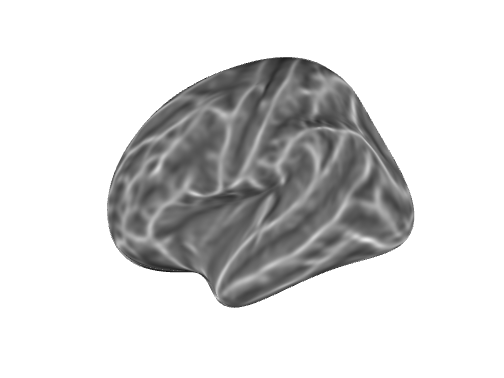

[underlay, colormapSG, ticksSG] = patchUnderlaySG(underlay, ...
    'lh', sglh, ...                   % At this stage, we do need to specify which hemipshere as often we are working with hemispheres with identical vertex counts
    'rh', sgrh,...
    'invertColors','on');               % This means darker colors will map on to sulci for fsaverage (other templates do not require this)

### Adding colorbars

Note, the outputs will be structures that contain information about how the colors were mapped on the brain. In order to visualize the colorbars for this map, now you would use:

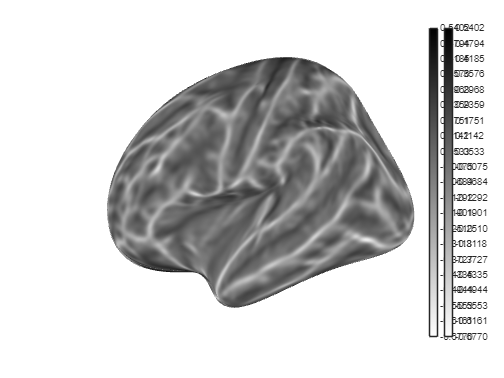

cbars = createBrainColorbar(colormapSG, ticksSG, 'FontSize', 8);  % Smaller font for better spacing, you may need to go lower

#### Controlling colorbars

As you can see above, there are two colorbars generated--one for each underlay. As you can also see, the bars can appear messy if you try to visualize both at once. At this point, you can turn off the colorbar for one of the surfaces to clean things up:

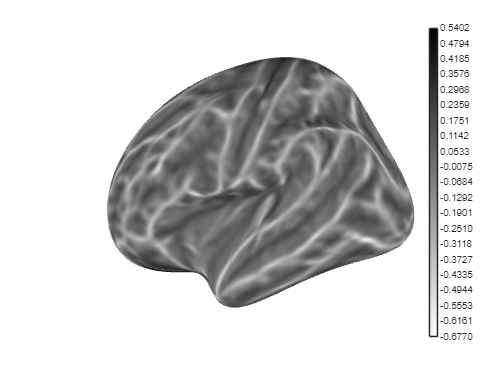

cbars.right.Visible = 'off'; % since we are viewing the left hemisphere at the moment...

#### Some other patchUnderlaySG options

Lots of arguments for patchUnderlaySG are optional--for example, binarizing the curv data, which we can do by specifying the binarize option. Here are a few optional arguments below with their default values that you may be especially interested in playing around with:

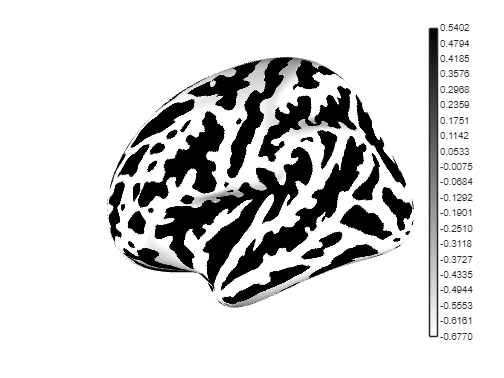

[underlay,colormapSG, ticksSG] = patchUnderlaySG(underlay, ...
    'lh', sglh, ...                   % At this stage, we do need to specify which hemipshere as often we are working with hemispheres with identical vertex counts
    'rh', sgrh, ...
    'colormap', 'gray', ...           % colormapper.m has other options you could try, check that functions' documentation (and for patchUnderlaySG.m)
    'invertColors', 'on', ...        % Disable color inversion--this means darker colors will map on to sulci for fsaverage (other templates do not require this)
    'limits', [0 1], ...              % Set appropriate limits for min/max values that will map on to the two ends of the colormap. This works well for fsaverage.
    'binarize', 0);                    % Many arguments are optional--this is the curv file threshold at which we apply binarization (everything below is 0 and above is 1)

At this point, we also need to update our colorbar:

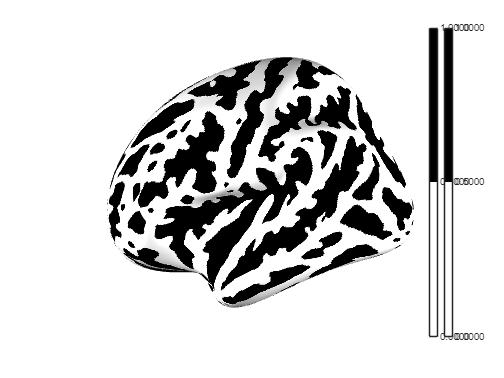

delete(cbars.left)
delete(cbars.right)
cbars = createBrainColorbar(colormapSG, ticksSG, 'FontSize', 8);  % Smaller font for better spacing, you may need to go lower

#### Controlling hemisphere visibility

The function patchUnderlaySG manipulates the colors in the underlying surface object. This means you need to change the underlay.?.FaceVertexCData to change colors on the surface itself, where ? represents the left or right hemispheres. This means that using delete on the surface object will remove both the surface and its colors. It's important to note this as you might like to omit visualizing a specific hemisphere. In such cases, instead of using delete, you can set the opacity of the underlay to 0:

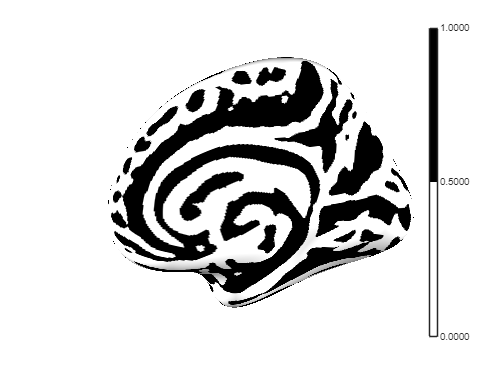

%delete(underlay.left) % instead of this, set opacity to zero for underlays
underlay.left.FaceAlpha = 0;
delete(cbars.right)

#### More patchUnderlaySG options

Here are some more changes we might make. Visualizing a different morphometry file is as simple as calling patchUnderlaySG again:

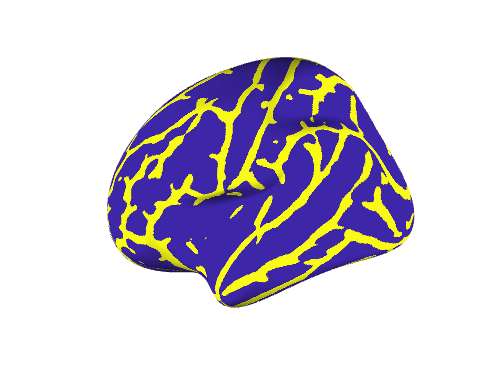

[underlay, ~, ~] = patchUnderlaySG(underlay, ...
    'lh', sglh, ...                   % At this stage, we do need to specify which hemipshere as often we are working with hemispheres with identical vertex counts
    'rh', sgrh, ...
    'colormap', 'parula', ...           % colormapper.m has other options you could try, check that functions' documentation (and for patchUnderlaySG.m)
    'invertColors', 'on', ...        % Disable color inversion--this means darker colors will map on to sulci for fsaverage (other templates do not require this)
    'thresh',[-0.1 0.1], ...
    'binarize', 0);                    % Many arguments are optional--this is the curv file threshold at which we apply binarization (everything below is 0 and above is 1)

delete(cbars.left);
delete(cbars.right);

#### Plotting an overlay on top of the surface and morphometry data

Let's load in the statistical we are interested in, then we'll patch some of it over our surface. Here we will patch data from the right hemisphere, which is not automatically visible. You can undock the figure and rotate it yourself, or keep following along to see how to change the view automatically

[hemiLH, ~, coactivationLH, ~, ~, ~] = loadBrainData([overlaysPath filesep 'MNI_CO_TTest_posneg_PCorrected0.001.nii_RF_ANTs_MNI152_orig_to_fsaverage_LH.nii.gz'], underlay, ln, rn);

Trying to load file: MNI_CO_TTest_posneg_PCorrected0.001.nii_RF_ANTs_MNI152_orig_to_fsaverage_LH.nii.gz
Attempting to load as conventional nifti file...


[hemiRH, ~, coactivationRH, ~, ~, ~] = loadBrainData([overlaysPath filesep 'MNI_CO_TTest_posneg_PCorrected0.001.nii_RF_ANTs_MNI152_orig_to_fsaverage_RH.nii.gz'], underlay, ln, rn);

Trying to load file: MNI_CO_TTest_posneg_PCorrected0.001.nii_RF_ANTs_MNI152_orig_to_fsaverage_RH.nii.gz
Attempting to load as conventional nifti file...


For patching overlays, we rely on the patchOverlay function. This function uses many others, including dataThresh to manipulate the data, including by applying thresholds.  Here is an example of how we might call that function for the two files we loaded in above:

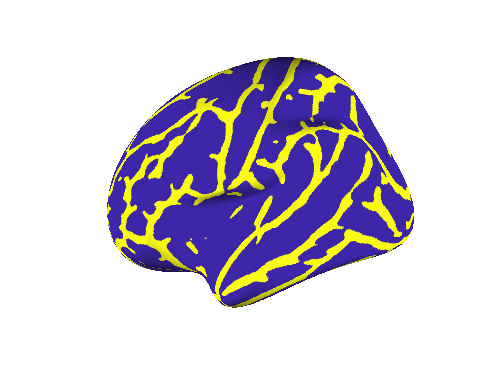

rhOverlay = patchOverlay(brainFig,coactivationRH,underlay,'right','colormap','thermal','opacity',0.8,'thresh',[-10 10]);

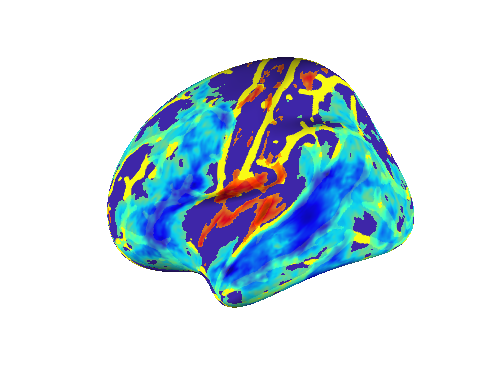

delete(lhOverlay)
[lhOverlay, colormaptmp, tickstmp] = patchOverlay(brainFig,coactivationLH,underlay,'left','colormap','jet','opacity',0.8);

Colorbars can be added as before, we just need to setup a .left and .right structure first as so

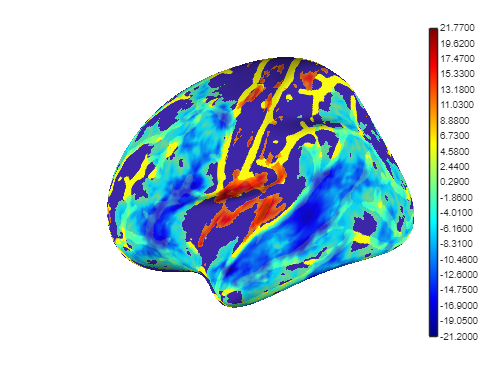

colormapOverlay.left = colormaptmp;
ticksOverlay.left = tickstmp;
cbars = createBrainColorbar(colormapOverlay, ticksOverlay, 'FontSize', 8);  % Smaller font for better spacing, you may need to go lower

And here is how we can automatically change the view of the figure

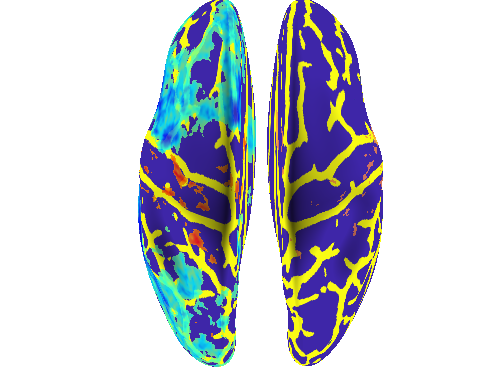

delete(cbars.left)
view(0,90)

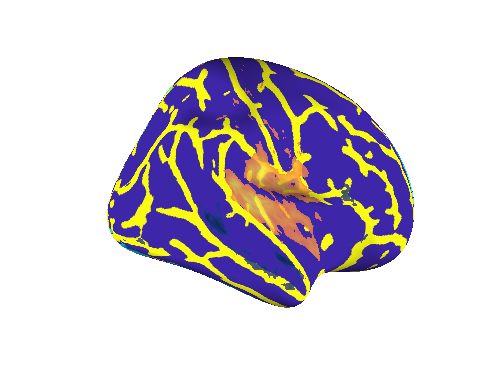

view(90,0)

For overlays, removing a patch is as simple as deleting the variable that stores it:

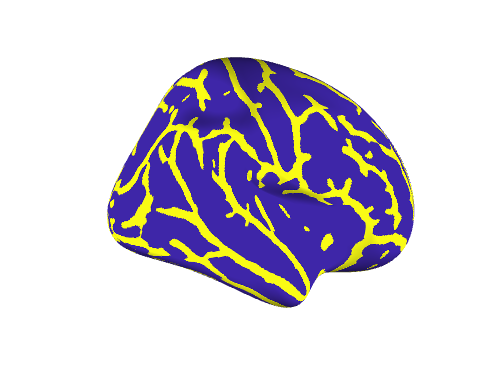

delete(lhOverlay);
delete(rhOverlay);

## Overlaying an atlas

loadAndProcessAtlas.m is used to load in our atlas data and organize it into a structure for downstream functions like the code below shows.

[atlas, sz] = loadAndProcessAtlas({[atlasPath filesep 'HCP_MMP1_fsaverage_L.nii.gz'],[atlasPath filesep 'HCP_MMP1_fsaverage_R.nii.gz']}, {'left','right'}, underlay, [atlasPath filesep 'HCP_MMP1_fsaverage.txt'])

Trying to load atlas: D:\Science\Matlab\GitHub\brainSurfer\atlases\HCP_MMP1_fsaverage_L.nii.gz
Attempting to load as conventional nifti file...
Trying to load atlas: D:\Science\Matlab\GitHub\brainSurfer\atlases\HCP_MMP1_fsaverage_R.nii.gz
Attempting to load as conventional nifti file...


atlas = struct with fields:
               bm: [1×1 struct]
          overlay: [1×1 struct]
             cBar: []
         cBarText: []
           cBarAx: []
          regions: [1×1 struct]
         clusters: [1×1 struct]
          borders: [1×1 struct]
             name: [1×1 struct]
             path: [1×1 struct]
    defaultColors: [1×1 struct]
      defaultCbar: [1×1 struct]


sz =       163842           1


For the most part, patching the atlas is like patching a statistical overlay. First, let's set up soe defaults we will use

% these are some default values
cmap = 'perceptually distinct'; % this colormap tries to construct the most distinct colorbar possible given a certain number of color bins
opacity = 1; % transparency
cspace = 'even'; % this determines how values are mapped on the colorbar. even is default, but for example, for continuous data with positive and negative values you could set this to 'center on zero' and have zero map on to the midpoint of the colorbar
minVal = max([1 min([min(atlas.bm.left) min(atlas.bm.right)])]); % here we get the smallest and largest values in our atlas in order to get unified limits across both hemispheres. We exclude zero.
maxVal = max([max(atlas.bm.left) max(atlas.bm.right)]);
cbins = (maxVal-minVal)+1; % this is the number of bins in our colorbar

Now let's patch:

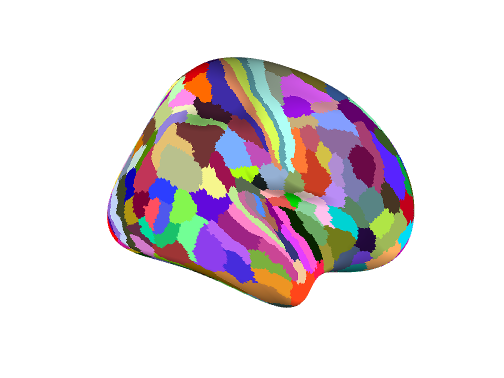

[atlas.overlay.left,cmapAtlasLH,ticksAtlasLH,~,~,~,transpAtlasLH,~] = patchOverlay(brainFig,atlas.bm.left,underlay,'left',...
    'opacity',opacity,'colormap',cmap,'colorSpacing',cspace,...
    'colorBins',cbins,'limits',[minVal maxVal],'priorClusters',atlas.clusters.left); % note the atlas.clusters.left and right fields contain the vertices associated with each ROI in the atlas

[atlas.overlay.right,cmapAtlasRH,ticksAtlasRH,~,~,~,transpAtlasRH,~] = patchOverlay(brainFig,atlas.bm.right,underlay,'right',...
    'opacity',opacity,'colormap',cmap,'colorSpacing',cspace,...
    'colorBins',cbins,'limits',[minVal maxVal],'priorClusters',atlas.clusters.right);

As before, you can experiment with the outputs of patch overlay:

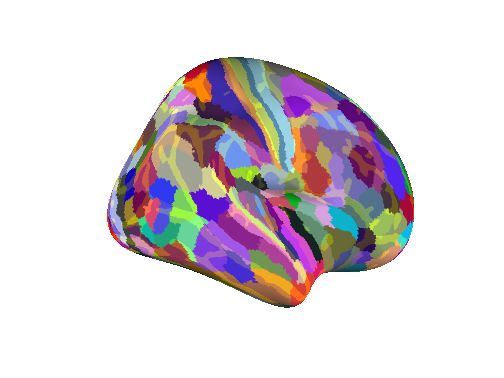

atlas.overlay.left.FaceAlpha = 0.8;
atlas.overlay.right.FaceAlpha = 0.8;

You can also outline the atlas regions. Our clusters field already contains boundaries for ROIs so we can simply remove other values from the main atlas intensities in our atlas structure

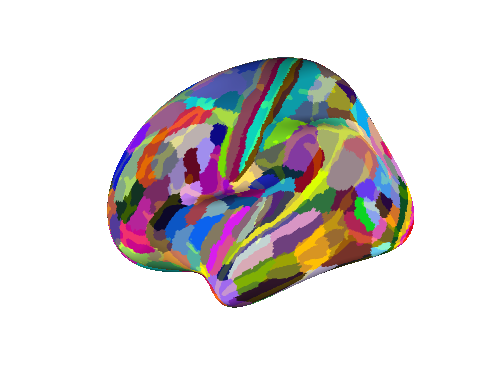

view(-90,0) % let's make sure we go back to the left hemisphere

clear hemi; hemi{1} = 'left'; % here is how you might automatically code hemisphere data after identifying it during the data loading process

% First, we need to remove some values
atv = unique(vertcat(atlas.borders.(hemi{1}){:})); % combine all clusters into one vector
bm = atlas.bm.(hemi{1}); % write atlas to a temporary variable for easier processing with fields
av = [1:length(bm)]'; % get atlas vertex indices
t = setdiff(av,atv); % find vertices in atlas but not in clusters
bm(t) = 0; % make those zero
atlas.bm.(hemi{1}) = bm; % write the results back into our structure

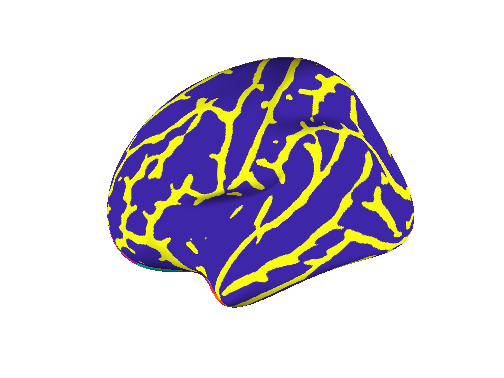

delete(atlas.overlay.(hemi{1})) % it is good practice to remove the old atlas

app.atlas.overlay.(hemi{1}) = []; % and setup a clean structure to use for the new one

Now we plot the atlas as boundaries

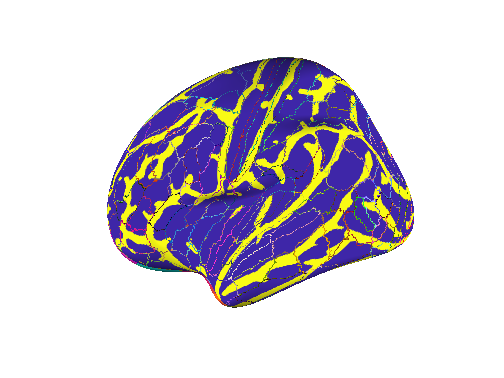

[atlas.overlay.(hemi{1}), cmapAtlasRH, ticksAtlasRH, ~, ~, ~, transpAtlasRH, ~] = patchOverlay(brainFig, atlas.bm.(hemi{1}), underlay, hemi{1}, ...
    'opacity', opacity, ...
    'colormap', cmap, ...
    'colorSpacing', cspace, ...
    'inclZero', 'off', ...
    'invertColors', 'off', ...
    'colorBins', cbins, ...
    'limits', [minVal maxVal], ...
    'priorClusters', atlas.clusters.(hemi{1}));

And we can easily manipulate the thickness of the lines

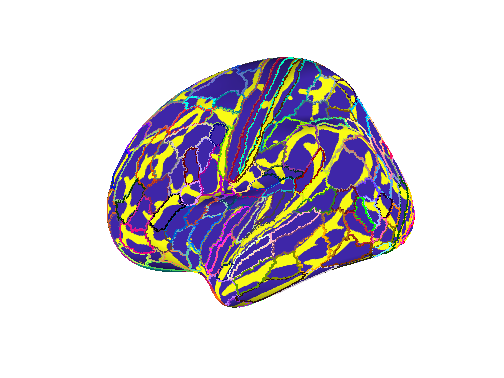

atlas.overlay.(hemi{1}).LineStyle = '-'; 
atlas.overlay.(hemi{1}).EdgeColor = 'flat';
atlas.overlay.(hemi{1}).LineWidth = 1; % this can increase the boundary size--2 is a good place to start but you cannot set it to zero or a negative value
atlas.overlay.(hemi{1}).EdgeAlpha = 'flat';

Of course, we can also patch a statistical map at the same time:

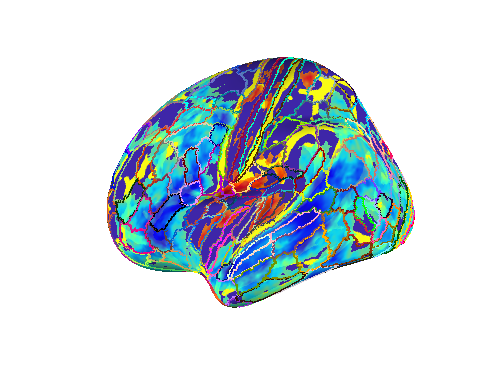

delete(lhOverlay); % just in case this was not previously deleted
lhOverlay = patchOverlay(brainFig,coactivationLH,underlay,'left','colormap','jet','opacity',0.8);

And you can attach the ROI text data we loaded in while loading atlas data so that when a datatip is placed on the brain, the ROI name is displayed. This is not as streamlined as the brainSurfer GUI but will still display ROI names.** Just make sure to hover on the right side of the patch below and click the "open in figure window" (this will provide a less buggy experience than inline mlx patches) for interactivity:**

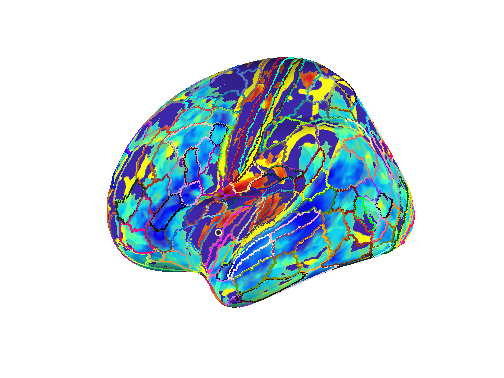

% To be safe, delete any previous data tips
dcm = datacursormode(gcf);
datatips = findall(gcf, 'Type', 'datatip');
delete(datatips);

% Assign user data
underlay.left.UserData = strrep(atlas.regions.left, '_', ' '); % replace underscore with space, otherwise matlab will use the underscore as an indicator to display the following letter as a subscript

% Make sure overlay does not interfere (it still will, but only within the
% mlx code, just click "open in figure window")
lhOverlay.HitTest = 'off';          % Disable hit testing
lhOverlay.PickableParts = 'none';   % Make the overlay non-pickable

% Set up the custom data tip function
dcm_obj = datacursormode(brainFig);
datacursormode on; % Ensure data cursor mode is active
set(dcm_obj, 'UpdateFcn', @underlayDataTip);

% Nested function for displaying ROI info
function txt = underlayDataTip(~, event_obj)
    % Get the target graphics object (the underlay)
    target = event_obj.Target;

    % Get the position of the data cursor
    pos = event_obj.Position;

    % Get the vertices and region names from the underlay
    v = target.Vertices;
    regionNames = target.UserData;

    % Find the index of the vertex closest to the cursor position
    [~, idx] = min(sum((v - pos).^2, 2));

    % Get the region name corresponding to the vertex
    if iscell(regionNames)
        regionName = regionNames{idx};
    else
        regionName = regionNames(idx);
    end

    % Create the text to display in the data tip
    txt = {
        ['X: ', num2str(pos(1), '%.2f')]
        ['Y: ', num2str(pos(2), '%.2f')]
        ['Z: ', num2str(pos(3), '%.2f')]
        ['Region: ', regionName]
    };
end

% Get vertex coordinates for a random vertex
vertex_coords = underlay.left.Vertices(5000,:);

% Create datatip there
dcm = datacursormode(gcf);
dt = createDatatip(dcm, underlay.left);
dt.Position = vertex_coords;

## Loading other underlays 

Depending on the type of file you are trying to load, you may need to use other functions. Underlays are not handled with a single automatic function in the same way as other brain data:

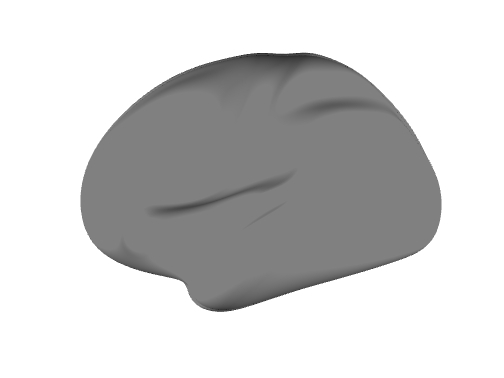

g = gifti([underlaysPath filesep 'S900.L.very_inflated_MSMAll.32k_fs_LR.surf.gii']);
g2 = gifti([underlaysPath filesep 'S900.R.very_inflated_MSMAll.32k_fs_LR.surf.gii']);
[underlay, brainFig, ~, ~] = patchUnderlay(g.vertices, g.faces, g2.vertices, g2.faces);

[hemiLH, hemiRH, sglh, sgrh, ~, ~] = loadBrainData([underlaysPath filesep 'S900.sulc_MSMAll.32k_fs_LR.dscalar.nii'], underlay, ln, rn);

Trying to load file: S900.sulc_MSMAll.32k_fs_LR.dscalar.nii
Attempting to load as conventional nifti file...
ERROR: D:\Science\Matlab\GitHub\brainSurfer\brains\S900.sulc_MSMAll.32k_fs_LR.dscalar.nii: hdr size = 540, should be 348
NIFTI LOAD FAILED!
Attempting to load as gifti file...
GIFTI LOAD FAILED!
Attempting to load as cifti file...


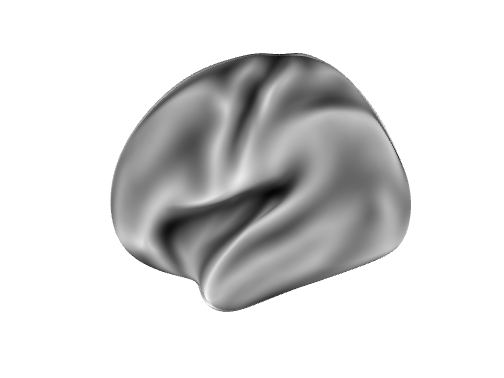

[underlay, colormapSG, ticksSG] = patchUnderlaySG(underlay, ...
    'lh', sglh, ...                   
    'rh', sgrh,...
    'invertColors','off');       

## Projecting volume space maps and thresholding maps

For simplicity, we will use the fsaverage surface for demonstrating map projection. First, let's load up the underlay as we did before but in one single go:

[vertlh,facelh] = read_surf([underlaysPath filesep 'lh.inflated']);
[vertrh,facerh] = read_surf([underlaysPath filesep 'rh.inflated']);
[underlay, brainFig, ~, ~] = patchUnderlay(vertrh, facerh, vertlh, facelh);
[hemiLH, ~, sglh, ~, ~, ~] = loadBrainData([underlaysPath filesep 'lh.curv'], underlay, ln, rn);

Trying to load file: lh.curv
Attempting to load as conventional nifti file...
ERROR: D:\Science\Matlab\GitHub\brainSurfer\brains\lh.curv: hdr size = 16777215, should be 348
NIFTI LOAD FAILED!
Attempting to load as gifti file...
GIFTI LOAD FAILED!
Attempting to load as cifti file...
CIFTI LOAD FAILED!
Attempting to load as annotation file...
ANNOTATION LOAD FAILED!
Attempting to load as label...
ERROR: could not open D:\Science\Matlab\GitHub\brainSurfer\brains\lh.curv.label
Attempting to load as freesurfer morphometry file...


[hemiRH, ~, sgrh, ~, ~, ~] = loadBrainData([underlaysPath filesep 'rh.curv'], underlay, ln, rn);

Trying to load file: rh.curv
Attempting to load as conventional nifti file...
ERROR: D:\Science\Matlab\GitHub\brainSurfer\brains\rh.curv: hdr size = 16777215, should be 348
NIFTI LOAD FAILED!
Attempting to load as gifti file...
GIFTI LOAD FAILED!
Attempting to load as cifti file...
CIFTI LOAD FAILED!
Attempting to load as annotation file...
ANNOTATION LOAD FAILED!
Attempting to load as label...
ERROR: could not open D:\Science\Matlab\GitHub\brainSurfer\brains\rh.curv.label
Attempting to load as freesurfer morphometry file...


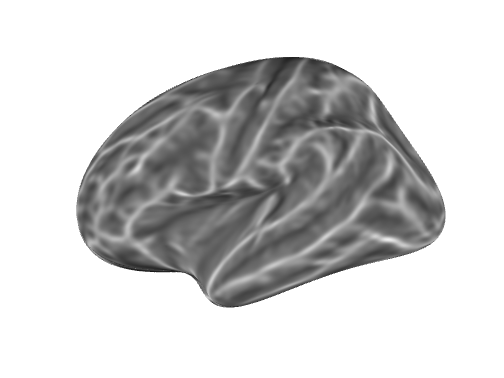

[underlay, colormapSG, ticksSG] = patchUnderlaySG(underlay, ...
    'lh', sglh, ...                   
    'rh', sgrh,...
    'invertColors','on');   

This function will project your data (you can leave the default option for an unthresholded statistical map but see the function for other options). Below we project a meta-analysis from neurosynth of the default mode network:

[hemi,hemi2,d,d2,tmpOut] = vol2fsaverage([overlaysPath filesep 'multidim' filesep 'default_mode.nii.gz_specificity_z.nii.gz']);

Now we patch the projected data and add some thresholds. Note also that vol2fsaverage wrote some files for us that we can come back to later.

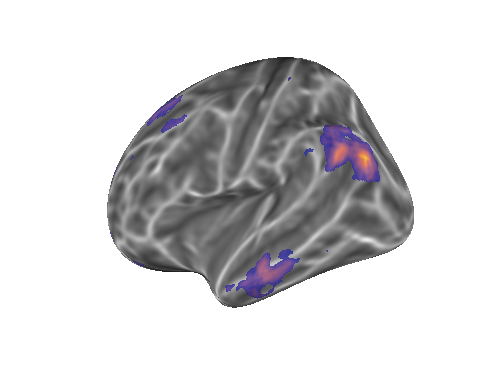

delete(lhOverlay); delete(rhOverlay);
lhOverlay = patchOverlay(brainFig,d,underlay,hemi,'colormap','thermal','opacity',0.85,'thresh',[-100 2.3]); % this will threshold out all negative values up to a positive z-score of 2.3 for the map
rhOverlay = patchOverlay(brainFig,d2,underlay,hemi2,'colormap','thermal','opacity',0.85,'thresh',[-100 2.3]); % this will threshold out all negative values up to a positive z-score of 2.3 for the map

#### Extending the example above: outlining the entire map

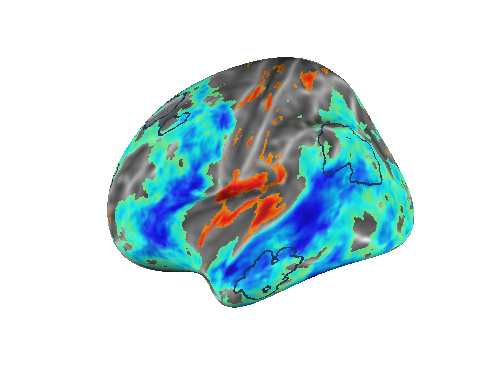

delete(lhOverlay);
lhOverlay = patchOverlay(brainFig,coactivationLH,underlay,'left','colormap','jet','opacity',0.8);
lhOverlay2 = patchOverlay(brainFig,d,underlay,hemi,'colormap','thermal','opacity',0.85,'thresh',[-100 2.3], ...
    'clusterThresh',200,'binarize','map','outline','map','grow',2); % we will remove all clusters under 200 vertices in size and binarize the entire map, then outline it

We can also shrink the map boundaries in the other direction. In other words, the vertices on the inside of the areas surviving threshold will be expanded 

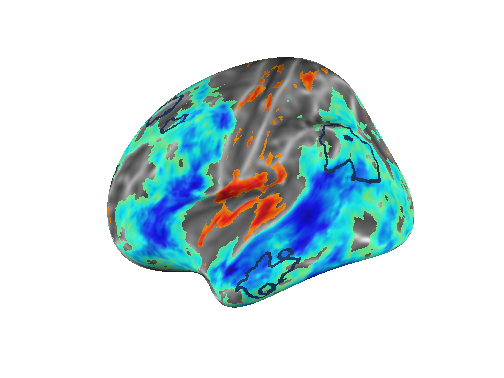

delete(lhOverlay2);
lhOverlay2 = patchOverlay(brainFig,d,underlay,hemi,'colormap','thermal','opacity',0.85,'thresh',[-100 2.3], ...
    'clusterThresh',200,'binarize','map','outline','map','grow',-2); % we will remove all clusters under 200 vertices in size and binarize the entire map, then outline it

We can also outline each cluster of vertices in the map instead of outlining the entire map, which will assign different colors to different clusters:

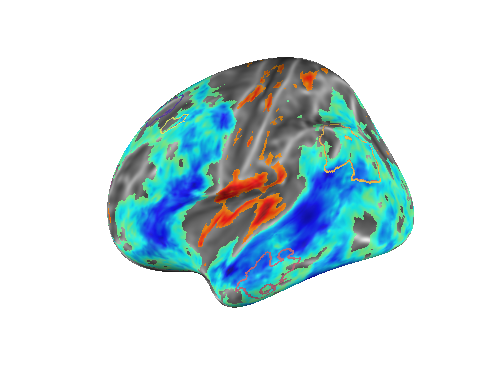

delete(lhOverlay2);
lhOverlay2 = patchOverlay(brainFig,d,underlay,hemi,'colormap','thermal','opacity',0.85,'thresh',[-100 2.3], ...
    'clusterThresh',200,'binarize','clusters','outline','map','grow',-1); % note we changed the binarize option here and changed the growVal so that the boundary is not assigned edge values before binarization occurs (i.e., causing the grown boundary to be assigned a different color)